Function

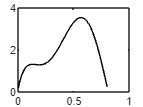

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = linspace(0, 0.8);
yy = f(xx);
plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 0;
b = 0.8;

p = [400 -900 675 -200 25 0.2];
q = polyint(p);

Itrue = diff(polyval(q, [a b]))

Itrue = 1.6405

Plot original function along with simpson 3/8 rule with ns = 1

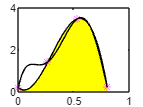

ns = 1;
x = linspace(0, 0.8, 3*ns+1);
y = f(x);

p3 = polyfit(x,y,3);
yy3 = polyval(p3,xx);

figure
area(xx,yy3,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(x,y,'m*')
hold on
plot(xx,yy,'k-')
hold off


p = p3

p =   -53.8889   48.8889   -4.5822    0.2000


q = polyint(p);
I1 = diff(polyval(q, [a b]))

I1 = 1.5192

et1 = (Itrue - I1)/Itrue*100

et1 = 7.3978

Plot original function along with simpson 3/8 rule with ns = 2

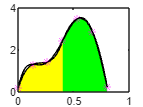

ns = 2;
x = linspace(0, 0.8, 3*ns+1);
y = f(x);

figure
color = ['g','y'];

for i = 1:ns
    il = 3*(i-1)+1;
    ir = 3*i+1;
    newx = x(il:ir);
    newy = y(il:ir);

    p3 = polyfit(newx, newy, 3);

    xx3 = linspace(x(il), x(ir));
    yy3 = polyval(p3, xx3);

    area(xx3,yy3,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on
end

plot(xx,yy,'k-')
hold off

Plot original function along with simpson 3/8 rule with ns = 3

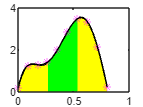

ns = 3;
x = linspace(0, 0.8, 3*ns+1);
y = f(x);

figure
color = ['g','y'];

for i = 1:ns
    il = 3*(i-1)+1;
    ir = 3*i+1;
    newx = x(il:ir);
    newy = y(il:ir);

    p3 = polyfit(newx, newy, 3);

    xx3 = linspace(x(il), x(ir));
    yy3 = polyval(p3, xx3);

    area(xx3,yy3,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on
end

plot(xx,yy,'k-')
hold off

Plot original function along with simpson 3/8 rule with ns from 1 to 10

fprintf("---------------------")

---------------------

ns = 1

ns = 2

ns = 3

ns = 4

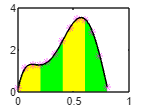

ns = 5

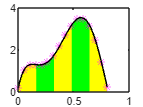

ns = 6

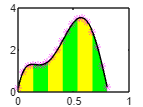

ns = 7

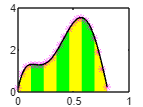

ns = 8

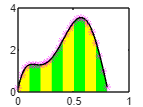

ns = 9

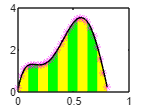

ns = 10

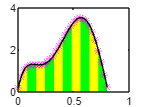


for ns = 1:10

    ns
    x = linspace(0, 0.8, 3*ns+1);
    y = f(x);

    figure
    color = ['g','y'];

    for i = 1:ns
        il = 3*(i-1)+1;
        ir = 3*i+1;
        newx = x(il:ir);
        newy = y(il:ir);
    
        p3 = polyfit(newx, newy, 3);
    
        xx3 = linspace(x(il), x(ir));
        yy3 = polyval(p3, xx3);
    
        area(xx3,yy3,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
        hold on
        plot(x(il:ir),y(il:ir),'m*')
        hold on
    end

plot(xx,yy,'k-')
hold off

end